% Optimize Classification Tree
% This example shows how to optimize hyperparameters automatically using fitctree. 
% The example uses Fisher's iris data.
% Load Fisher's iris data.
load fisheriris
X = meas;
Y = species;

% 不经过优化的训练分类树
Md0 = fitctree(X,Y);
% 计算分类模型Md0中的损失函数
resuberror = resubLoss(Md0)   % resuberror =  0.0200

resuberror = 0.0200

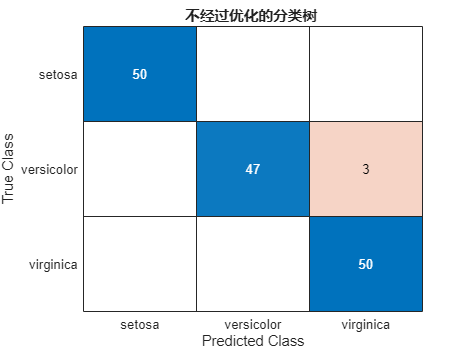

% 预测
cc0=predict(Md0,meas);
figure
cm0 = confusionchart(species,cc0);
cm0.Title = '不经过优化的分类树 ';

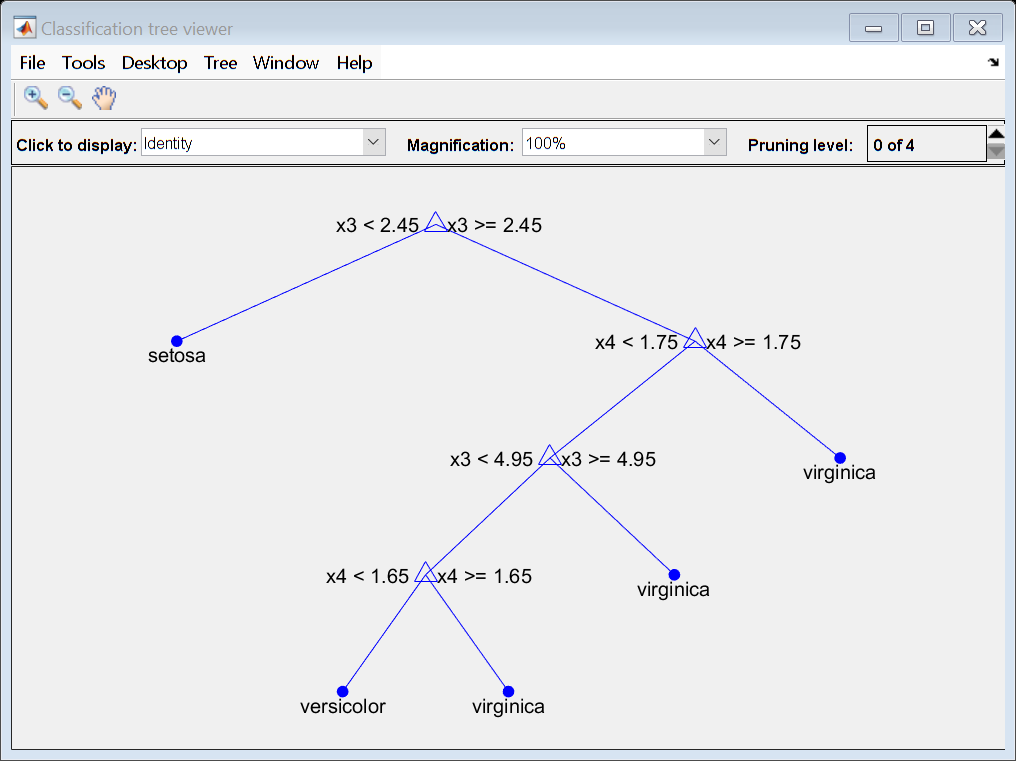

% 展示结构
view(Md0,'Mode','graph');

|======================================================================================|
| Iter | Eval   | Objective   | Objective   | BestSoFar   | BestSoFar   |  MinLeafSize |
|      | result |             | runtime     | (observed)  | (estim.)    |              |
|======================================================================================|
|    1 | Best   |    0.033333 |     0.98522 |    0.033333 |    0.033333 |            2 |
|    2 | Accept |     0.66667 |      0.3192 |    0.033333 |    0.066084 |           72 |
|    3 | Accept |    0.046667 |     0.10098 |    0.033333 |    0.081944 |           24 |
|    4 | Accept |    0.046667 |    0.065775 |    0.033333 |    0.084552 |            7 |
|    5 | Accept |    0.046667 |     0.14664 |    0.033333 |    0.033351 |           22 |
|    6 | Accept |        0.04 |    0.039951 |    0.033333 |    0.033649 |            5 |
|    7 | Accept |        0.04 |    0.038817 |    0.033333 |    0.038689 |            1 |
|    8 | Accept |    

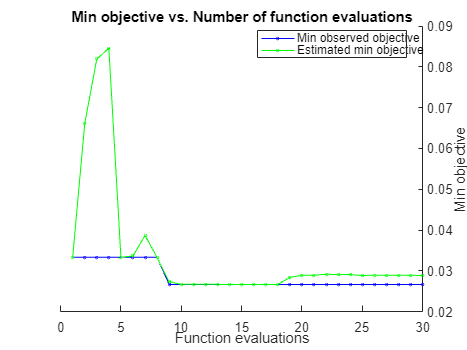

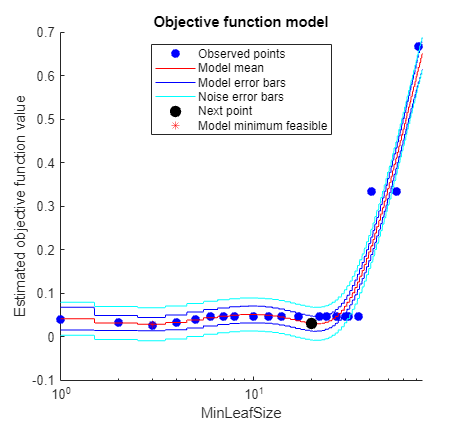

Mdl =   ClassificationTree
                         ResponseName: 'Y'
                CategoricalPredictors: []
                           ClassNames: {'setosa'  'versicolor'  'virginica'}
                       ScoreTransform: 'none'
                      NumObservations: 150
    HyperparameterOptimizationResults: [1×1 BayesianOptimization]


  Properties, Methods




% 经过优化的训练分类树
% rng(12345) %  resuberror =    0.0267
rng(6794050) %  resuberror =  0.0267

% Optimize the cross-validation loss of the classifier, 
% using the data in meas to predict the response in species.
Mdl = fitctree(X,Y,'OptimizeHyperparameters','auto')

% 计算分类模型Mdl中的损失函数
resuberror = resubLoss(Mdl)

resuberror = 0.0267

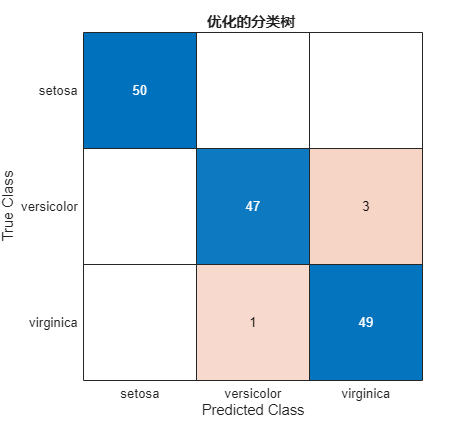


% 预测
cc1=predict(Mdl,meas);
cm1 = confusionchart(species,cc1);
cm1.Title = '优化的分类树 ';

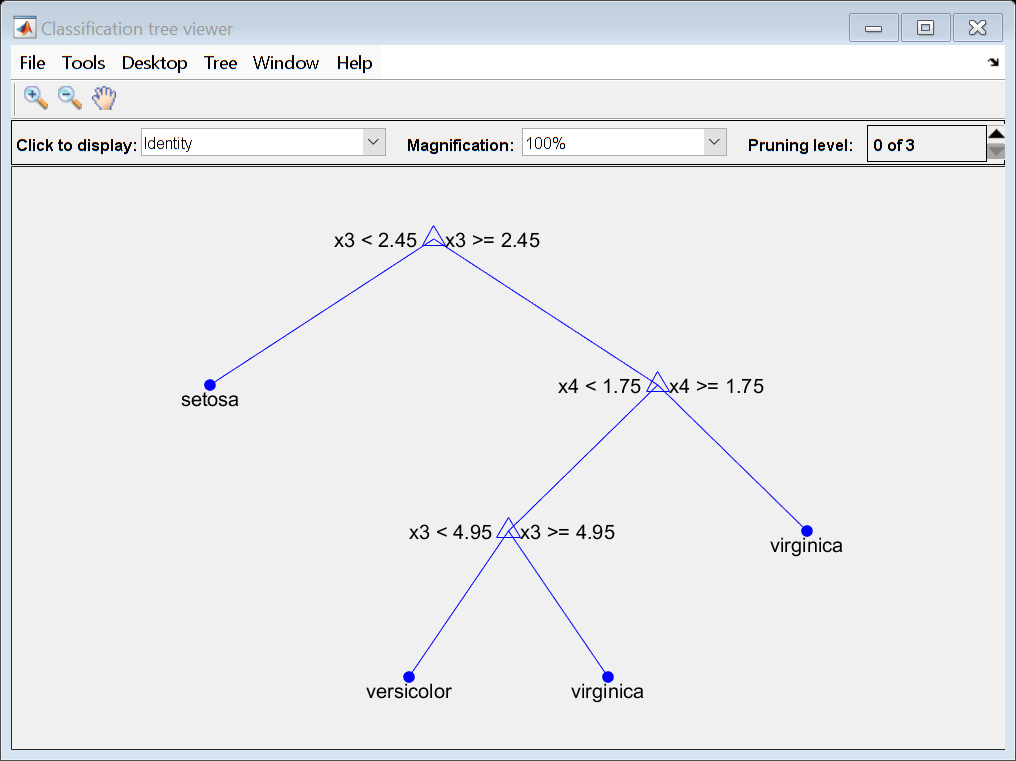


% 展示结构
view(Mdl,'Mode','graph');


% 本示例因为数据规模太小，所有数据集都作为了训练集
% 经过优化后，损失函数还略微变差了
% 但是模型树的结构精简了，泛化能力可能提高了